# PMSM Analysis

Let's consider a PMSM with the following electrical characteristics:

Rs = 0.013 % Stator phase resistance (Ω)

Rs = 0.0130

Ld = 0.00022 % Stator d-axis inductance (H)

Ld = 2.2000e-04

Lq = 0.00022 % Stator q-axis inductance (H)

Lq = 2.2000e-04

L0 = 0.00016 % Stator zero-sequence inductance (H)

L0 = 1.6000e-04

PsiM = 0.03 % Permanent magnet flux linkage (Wb)

PsiM = 0.0300

N = 6 % Number of pole pairs

N = 6

And mechanical characteristics:

J = 0.01 % Rotor inertia (kg*m2)

J = 0.0100

k = 0 % Rotor damping (N*m*s/rad)

k = 0

The PMSM and its Motor Control Unit (MCU) can be simulated with the following Simulink model:

mdl = 'TopModel';
open_system(mdl);

As a first example, we can simulate its behavior when we short circuit the 3 phases and just apply a torque to the PMSM for 1 s to see the phase currents we obtain:

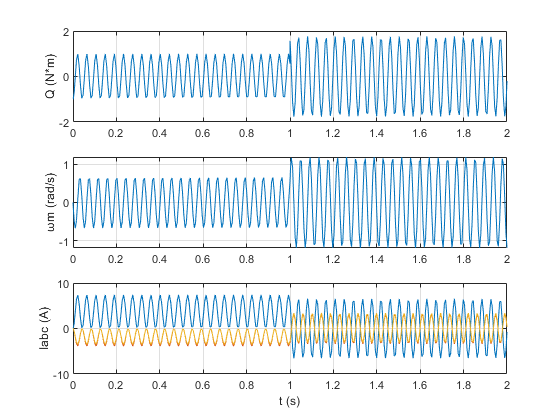

Tsim = 2; % Simulation time (s)
simIn = Simulink.SimulationInput(mdl);
simIn = simIn.setModelParameter('StopTime', num2str(Tsim));
ds = createInputDataset(mdl);
ds{1} = ds{1}.delsample('Index', [1 2]);
ds{1} = ds{1}.addsample('Time', [0 Tsim]', 'Data', [true true]');
ds{2} = ds{2}.delsample('Index', [1 2]);
ds{2} = ds{2}.addsample('Time', [0  1  1 Tsim]', 'Data', [1 1 0 0]');
simIn = simIn.setExternalInput(ds);
simOut = sim(simIn);

figure()
for ii = 1:3
    subplot(3, 1, ii);
    plot(simOut.tout, simOut.yout{ii}.Values.Data);
    ylabel([simOut.yout{ii}.Name ' (' ...
        simOut.yout{ii}.Values.DataInfo.Units.Name ')']);
    grid();
end
xlabel('t (s)');